clc;clear;close all
fprintf('\nTraining SVM with RBF Kernel (this may take 1 to 2 minutes) ...\n');


Training SVM with RBF Kernel (this may take 1 to 2 minutes) ...


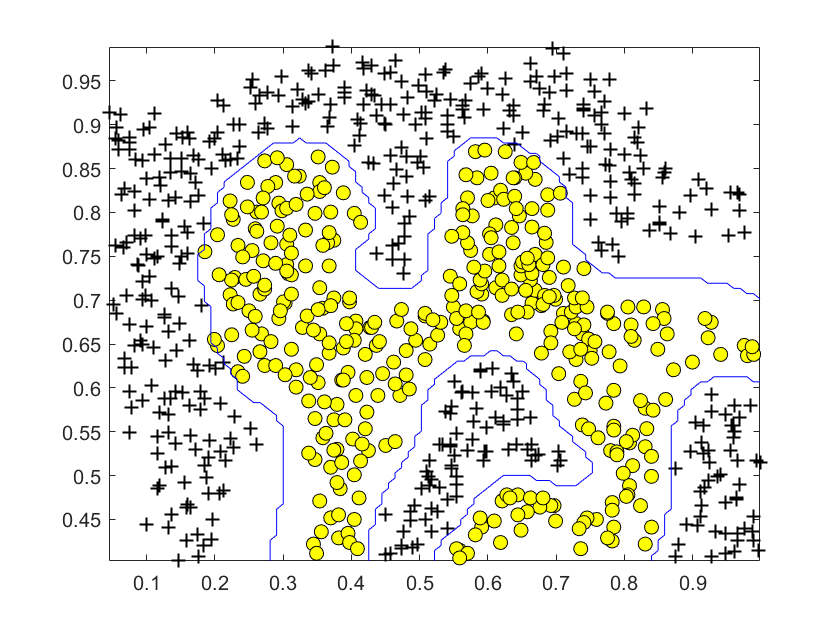


% Load from ex6data2: 
% You will have X, y in your environment
load('ex6data2.mat');

% SVM Parameters
C = 1; sigma = 0.1;

% We set the tolerance and max_passes lower here so that the code will run
% faster. However, in practice, you will want to run the training to
% convergence.
% model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma))
model = fitcsvm(X,y,'Standardize',true,'KernelFunction','RBF',...
    'KernelScale','auto');
visualizeBoundary(X, y, model);


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.
